# Optimierung für Industrielogistiker

## Übungsaufgabe 2

Programmieren Sie den 3-Punkt-Muster-Algorithmus aus dem Skriptum aus. Benützen Sie dafür den unten stehenden Code.

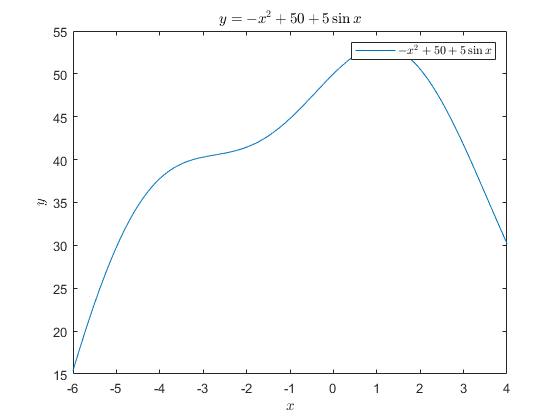

clear variables;
clc;

f = @(x) -x.^2 + 50 + 5 * sin(x);
X_U = -6;
X_O = 4;
x = linspace(X_U, X_O, 1000000);
y = f(x);
plot(x, y);
title('$y = -x^2 + 50 + 5 \sin x$', 'interpreter', 'latex');
xlabel('$x$', 'interpreter', 'latex');
ylabel('$y$', 'interpreter', 'latex');
legend('$-x^2 + 50 + 5 \sin x$', 'interpreter', 'latex');

DELTA = 1;
[xu, xmidpoint, xo] = threepointpatternsearchmethod(f, X_U, DELTA);
disp(['x_u = ', num2str(xu, '%.8f'), ', x_midpoint = ', num2str(xmidpoint, '%.8f'), ', x_o = ', num2str(xo, '%.8f')])

x_u = -3.00000000, x_midpoint = 1.00000000, x_o = 9.00000000
